# Модуляция с остаточной боковой полосой

# Vestigial Side Band

# (VSB)

**Для запуска скриптов необходимо корневую папку репозитория сделать рабочей папкой Matlab!**

### 1. Введение

Вид модуляции, который является промежуточным вариантом между DSB и SSB и сочетает преимущества обоих методов, называется модуляция с остаточной боковой полосой (Vestigial Side Band - VSB). В данной методе модуляции одна из половин спектра сигнала удаляется не полностью, как в SSB, а лишь частично. Полоса сигнала при этом будет больше, чем у однополосного сигнала, но меньше чем у DSB. В какой-то мере можно сказать, что VSB сочетает преимущества и недостатки DSB и SSB.

### 2. Модулятор VSB

Чтобы сформировать VSB сигнал, необходимо удалить часть у одной из половин спектра. Это можно сделать уже на несущей частоте с помощью полосового фильтра, или еще на нулевой частоте с помощью фильтра нижних частот. Последний вариант более пердпочтителен, и ни чем не отличается от "третьего метода" для SSB модуляции.

Спектр действительного информационного ссобщения симметричен относительно нулевой частоты. Этот спектр можно подвинуть с помощью умножения на комплексную экспоненту. Сигнала при этом станет комплексным. Если теперь подать этот сигнал на фильтр, полоса которого больше половины полосы спектра, но меньше, чем вся полоса, то мы получим VSB сигнал. Если в частотной области сигнал был сдвинут в сторону отрицательных частот, то будет обрезана нижняя половина спектра. Этот сигнала можно назвать USB VSB. Если сдвигать в область положительных частот, то обрежется верхняя половина, и мы получим LSb VSB.

После фильтрации сигнал умножается на несущую и передается в эфир. В этом случае, сигнал не будет в явном виде содержать гармонику на частоте несущей, поэтому такой сигнал называют VSB-SC. Если до первого сдвига спектра к сообщению добавить постоянную составляющую, то получим VSB-TC. 

Схема передающего устройства совпадает со схемой, представленной в VSB Transmitter:

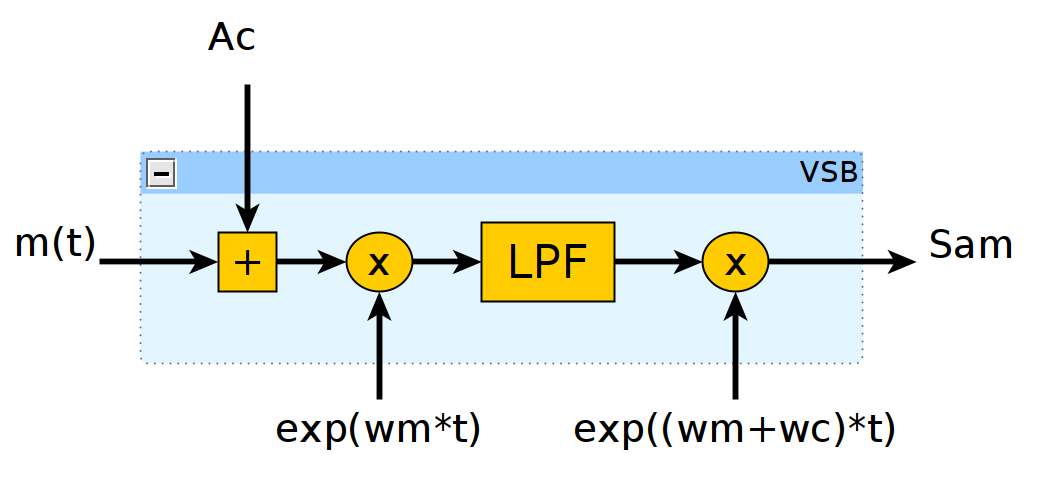

Ниже представлен скрипт для получения VSB сигнала при модуляции аудиосообщением. С помощью переменной ModulationMethod можно выбрать, какой сигнал будет сформирован: USB или LSB. Переменная Ас задает амплитуду несущей. ЕСли она равна нулю, то мы получим VSB-SC, иначе VSB-TC. Будем считать, что полоса исходного сообщения равна 22 kHz, и требуется, чтобы полоса VSB синала была равна 30 kHz. Таким образом, перед фильтрацией спектр сообщения нужно подвинуть на 22 - (30/2) = 6 kHz.  

Далее, чтобы сдвинуть сигнал на частоту несущей, после низкочастотной фильтрации его необходимо сдвинуть обратно на 6 kHz. Это можно сделать сразу во время переноса на несущую, умножая сигнал на комплексную экспоненту, частота которой равна сумме частоты несущей и частоты сдвига.

Скрипт выполняющий, описанные преобразования, представлен ниже:

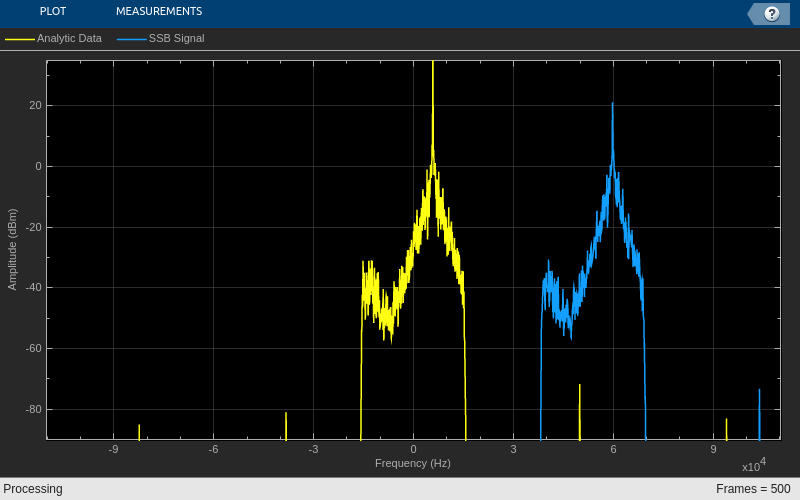

clc; clear; close all;
addpath('matlab/VSB');

AudioFrameSize = 1000;  % количество отсчетов аудиофайла, получаемых за один раз
FramesNumber = 500;     % число обрабатываемых пачек данных
RateRatio = 5;          % коэффициент увеличения частоты дискретизации
Ac = 2;                 % амплитуда несущей

% выбор метода модуляции
ModulationMethod = "LSB"; 

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    'wav/Audio_Source.wav', ...
    'SamplesPerFrame',AudioFrameSize...
    );

% дополнительные расчеты
AudioFs = AudioReader.SampleRate;               % получаем частоту дискретизации аудиосообщения
SignalFs = AudioFs * RateRatio;                 % частота дискретизации модулированного сигнала
SignalFrameSize = AudioFrameSize * RateRatio;   % количество отсчетов Ам-сигнала, получаемых за один раз

% генератор тона с частотой 11 kHz
BasebandMixer = dsp.SineWave(...
    'SampleRate', AudioFs,...
    'SamplesPerFrame', AudioFrameSize,...
    'Frequency', 6e3,...
    'ComplexOutput', true, ...
    'Amplitude', 1);

% расчет коэффициентов и создание низкочастотного фильтра
H = Transmitter_Baseband_FIR_Coeff(); 
BasebandFIR = dsp.FIRFilter(H.Numerator);

% генератор несущей с частотой 60 kHz
Carrier_USB = dsp.SineWave(...
    'SampleRate', SignalFs,...
    'SamplesPerFrame', SignalFrameSize,...
    'Frequency', 60e3 + 6e3,...
    'ComplexOutput', true, ...
    'Amplitude', 1);

Carrier_LSB = dsp.SineWave(...
    'SampleRate', SignalFs,...
    'SamplesPerFrame', SignalFrameSize,...
    'Frequency', 60e3 - 6e3,...
    'ComplexOutput', true, ...
    'Amplitude', 1);

% интерполятор 
Upsampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate',AudioFs, ...
    'OutputSampleRate', SignalFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Analytic Data', 'SSB Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

VSBAmSignalArray = [];

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов аудиосообщения и выделение одного канала из
    % стерео сигнала
    AudioData = AudioReader();
    AudioData = AudioData(:,1);
    
    % добавление постоянной составляющей
    AudioData = AudioData + Ac;

    % формирование тона для переноса сперктра
    MixerWave = BasebandMixer(); 

    % фильтрация для удаления второй полосы
    if (ModulationMethod == "LSB")
        VSBData = BasebandFIR(AudioData.*MixerWave);
    else
        VSBData = BasebandFIR(AudioData.*conj(MixerWave));
    end

    % увеличение частоты дискретизации аудиосообщения
    UpsampledData = Upsampler(VSBData);
     
    % формирование несущей
    if (ModulationMethod == "LSB")
        CarrierWave = Carrier_LSB();    
    else
        CarrierWave = Carrier_USB();
    end

    % перенос на частоту несущей
    VSBAmSignal = UpsampledData.*CarrierWave;
    VSBAmSignalArray = [VSBAmSignalArray VSBAmSignal];

    % вычисление спектров
    SpectrumData = SpecEstimator([UpsampledData, VSBAmSignal]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end

Желтым цветом на графике представлен спектр сообщения после низкочастотной фильтрации, а синим - спектр модулированного сигнала. Можно увидеть, одна из половин спектра обрезана, и полоса сигнала равна 30 kHz.

### 3. Когерентная демодуляция VSB

Так как VSB является промежуточным вариантом между SSB и DSB, то его можно принимать когерентно с помощью умножения на колебание, частота и фаза которого совпадает с несущей. Схема приемника представлена ниже:

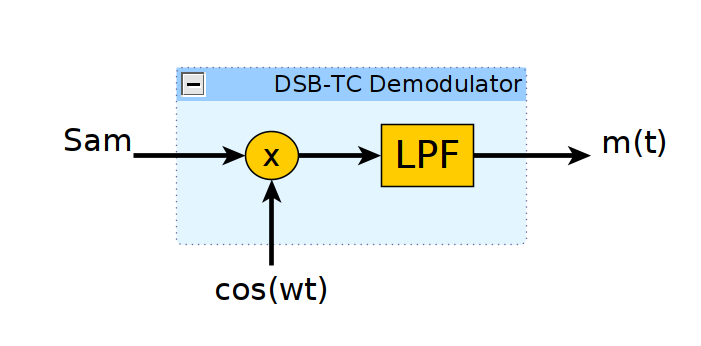

Скрипт, выполняющий демодулцию представлен ниже. С помощью переменных FreqOffset и PhaseOffset можно задать расстройку по частоте и фазе и на слух оценить оскажения сигнала. Перед запуском скрипта необходимо выполнить скрипт из параграфа 2.

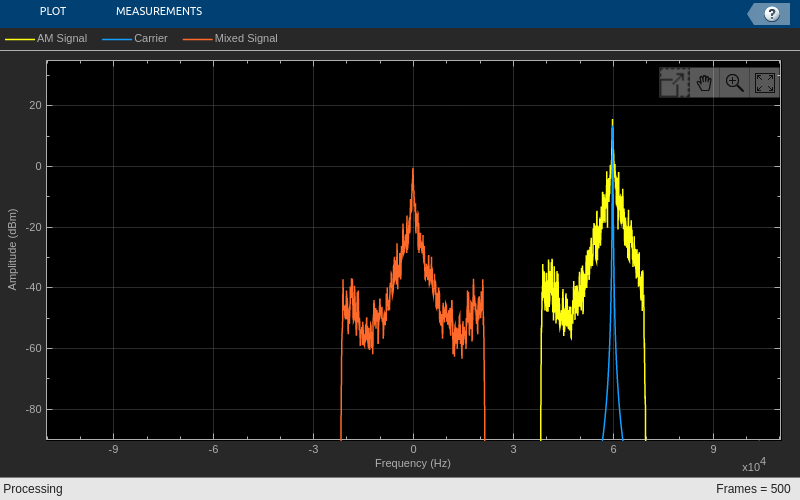

AudioAmp = 1; % коэффициент усиления аудиосигнала

FreqOffset = 0;             % расстройка по частоте (Hz)
PhaseOffset = 0 * pi/180;   % расстройка по фазе (градусы)

% генератор несущей для двух пользователей
Carrier = dsp.SineWave(...
    'SampleRate', SignalFs,...
    'SamplesPerFrame', SignalFrameSize,...
    'Frequency', 60e3 + FreqOffset,...
    'PhaseOffset', PhaseOffset, ...
    'ComplexOutput', true, ...
    'Amplitude', 1 ...
    );

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'AM Signal', 'Carrier', 'Mixed Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber

    % получение отсчетов сигнала
    VSBAmSignal = VSBAmSignalArray(:,i);

    % получение несущей
    CarrierWave = Carrier();

    % смешивание АМ-сигнала и несущей
    MixedSignal = VSBAmSignal .* conj(CarrierWave);
    MixedSignal = real(MixedSignal);

    % понижение частоты дискретизации
    Message = [Message; AudioAmp*DownSampler(MixedSignal)];

    % вычисление спектров
    SpectrumData = SpecEstimator([VSBAmSignal CarrierWave MixedSignal]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.03)
end

На графике желтым цветом представлен VSB сигнал, синим - гармоническое колебание в приемнике, красным - восстановленное сообщение. 

% проигрывание полученного сообщения
sound(Message, AudioFs);

На слух можно оценить, что искажения из за расстройки и частоте или фазе аналогичны, тем что были получены для DSB и SSB сигналов.

Стоит ответить следующий момент. При переносе на нулевую частоту, компоненты из одной урезанной половины спектра будут накладывать на компоненты из другой половины и усиливать их. Таким образом, одна часть спектра сообщения будет получать большее усиление, чем другая. Для нашего примера, сигнал имеет полосу в 30 kHz, при этом 22 kHz - это одна половина, и 8 kHz - это вторая уразанная часть. При наложении частье спектра, область частот от 0 до 8 kHz получит большее усиление, чем область от 8 до 22 kHz. Для нашего примера это не вызывает никаких искажений, но если это необходимо эту разность в усилениях можно убрать с помощью фильтра, с правильно подобранной АЧХ.

### 4. Удаление остаточной части спектра при демодуляции VSB

Помимо применения выравнивающего фильтра, АЧХ которого подобрана таким образм, чтобы компенсировать разность в усилении, можно воспользоваться методом разделения каналов, рассмотренным в SSB SC Receiver Part 2. 

После переноса на нулевую частоту, но перед выделение действительной части, VSB сигнал можно дополнительно отфильтровать, чтобы удалить компоненты спектра из образанной половины.

Ниже представлен скрипт, выполняющий описанные преобразования. Перед запуском скрипта необходимо выполнить скрипт из параграфа 2.

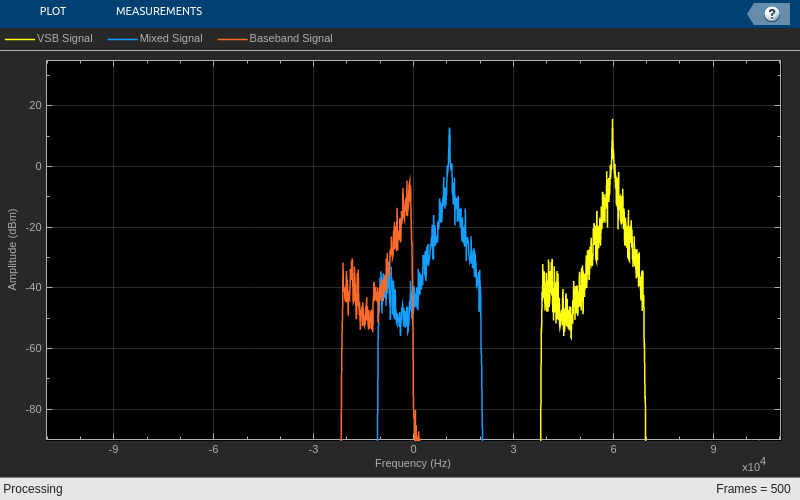

addpath('matlab/SSB_SC');

AudioAmp = 1; % коэффициент усиления аудиосигнала

% генератор несущей с частотой 60 kHz
Carrier_USB = dsp.SineWave(...
    'SampleRate', SignalFs,...
    'SamplesPerFrame', SignalFrameSize,...
    'Frequency', 60e3 + 11e3,...
    'ComplexOutput', true, ...
    'Amplitude', 1);

Carrier_LSB = dsp.SineWave(...
    'SampleRate', SignalFs,...
    'SamplesPerFrame', SignalFrameSize,...
    'Frequency', 60e3 - 11e3,...
    'ComplexOutput', true, ...
    'Amplitude', 1);

% расчет коэффициентов и создание низкочастотного фильтра
H = Receiver_Baseband_FIR_Coeff(); 
BasebandFIR = dsp.FIRFilter(H.Numerator);

% генераторы для переноса сигнала на нулевую частоту
BasebandMixer = dsp.SineWave(...
    'SampleRate', SignalFs,...
    'SamplesPerFrame', SignalFrameSize,...
    'Frequency', 11e3,...
    'ComplexOutput', true, ...
    'Amplitude', 1 ...
    );

% дециматор
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'VSB Signal', 'Mixed Signal', 'Baseband Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % получение отсчетов сигнала
    VSBAmSignal = VSBAmSignalArray(:,i);
    
    % получение несущей
    if (ModulationMethod == "LSB")
        CarrierWave = Carrier_LSB();
    else
        CarrierWave = Carrier_USB();
    end
    
    % смещение сигналов по частоте
    MixedData = VSBAmSignal .* conj(CarrierWave);
    
    % низкочастотная фильтрация
    FilteredData = BasebandFIR(MixedData);
    
    % получения комплексной экспоненты для компенсации сдвига по частоте
    BasebandWave = BasebandMixer();

    % компенсация сдвига по частоте
    if (ModulationMethod == "LSB")
        BasebandData = FilteredData .* conj(BasebandWave);
    else
        BasebandData = FilteredData .* BasebandWave;
    end

    % децимация
    AudioData = real(DownSampler(BasebandData));
    
    Message = [Message; AudioData];

    % вычисление спектров
    SpectrumData = SpecEstimator([VSBAmSignal MixedData BasebandData]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end

На спектрограмме спектрограмме показан исходный VSB сигнал (желтый). Синим показан сдвинутый по частоте исходный сигнал. Сдвиг выполняется таким образом, чтобы середина нужной половины спектра располагалась на нулевой частоте. Далее применяется фильтр нижных, частоте и все спектральные компоненты кроме нужной половины спектра удаляются. В завершении отфильтрованный сигнал сдвигается на нулевую частоту (красный).

% проигрывание полученного сообщения
sound(Message, AudioFs);

Можно услышать, что исходное сообщение восстанавливается без искажений.

### 5. Некогерентная демодуляция

Опять же, так как VSB сигнала совмещает в себе свойства DSB и SSB, то при определенных условиях его можно принимать некогерентно. В SSB TC Receiver было отмечено, что для случая DSB TC, чтобы использовать некогерентный метод приема необходимо выполнение условия ${\mathrm{A}}_c \ge \max \left\lbrace m\left(t\right)\right\rbrace$.  Для SSB TC требования более жесткие: ${\mathrm{A}}_c >>\max \left\lbrace m\left(t\right)\right\rbrace$. То есть, амплитуда несущей должна быть много больше максимального значения сообщения. 

Для VSB сигнала так же можно применять некогерентный приемник при условии ${\mathrm{A}}_c >>\max \left\lbrace m\left(t\right)\right\rbrace$. Однако, качество восстановления сообщения при увеличении амплитуды несущей улучшается быстрее, чем для SSB.

Для получаения огибающей комплексного сигнала достаточно вычислить его модуль. Воспользуемся тем же скриптом, который рассмотривается в DSB TC Receiver Part 3. Скрипт представлен ниже. Перед запуском скрипта необходимо выполнить скрипт из параграфа 2, помощью переменной Ас которого можно изменять амплитуду несущей. 

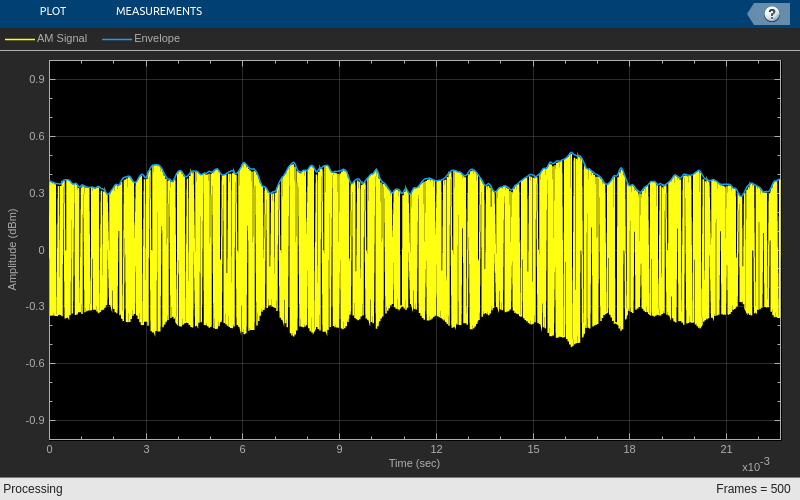

AudioAmp = 0.2; % коэффициент усиления аудиосигнала

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'YLimits', [-1, 1], ...
    'XLabel', 'Time (sec)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'AM Signal', 'Envelope'}, ...
    'SampleIncrement', 1/SignalFs ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % получение отсчетов сигнала
    VSBAmSignal = VSBAmSignalArray(:,i);

    % вычисление амплитуды сигнала
    AbsVSBAmSignal = abs(VSBAmSignal);

    % понижение частоты дискретизации
    Message = [Message; AudioAmp*DownSampler(AbsVSBAmSignal)];

    % вывод результатов на график
    Plotter([AudioAmp*real(VSBAmSignal) AudioAmp*AbsVSBAmSignal])

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end

Выше представлены временные диаграммы сигналов на входе (желтый цвет,принятом сообщении действительная составляющая) и выходе (синий цвет) демодулятора. 

% проигрывание полученного сообщения
sound(Message, AudioFs);

На слух можно обнаружить, что при меньшем значении амплитуды несущей в востановленном сигнале присутствуют искажения. При больше значении переменной Ас, сообщение восстанавливается без искажений. 

### Литература:

- B. P. Lathi Modern Digital and Analog Communication Systems

- R. Stewart, K. Barlee, D. Atkinson, L. Crockett Software Defined Radio using MATLAB® & Simulink and the RTL-SDR